clear all; close all;
load('Entire_region_Summer.mat')

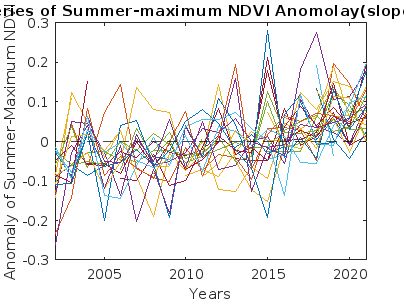

% plotting the time series of slope values greater than 0.005
A_pos = T.trend_slopes >= 0.005;
T_pos = [];
for i=1:27
    T_pos = [T_pos T{:,i}(A_pos)];
end
clear i; clear max_slope; clear min_slope; clear A;

T_pos = array2table(T_pos);
T_pos = renamevars(T_pos,T_pos.Properties.VariableNames, T.Properties.VariableNames);

for i = 1:sum(A_pos)
    plot(2002:2021, T_pos{i, 3:22} - T_pos{i,23})
    xlim([2002,2021]);%ylim([0,0.65]);
    xlabel("Years", 'FontName', "Dialog"); 
    ylabel("Anomaly of Summer-Maximum NDVI", 'FontName', "Dialog");
    title("Time series of Summer-maximum NDVI Anomolay(slope > 0.005", ...
        'FontName', "Dialog");
    hold on
end
yline(0,'k--')
clear A_pos; clear i
hold off
saveas(gcf,'Published_Plots\Figure_13.a.pdf')

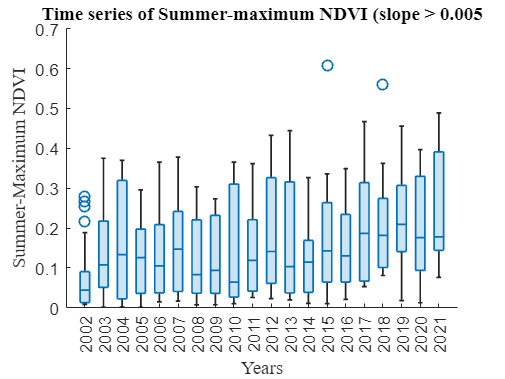

boxchart(T_pos{:,3:22})
set(gca,'XTickLabel',{'2002','2003','2004','2005', ...
    '2006','2007','2008','2009','2010','2011','2012','2013', ...
    '2014','2015','2016','2017', '2018','2019','2020','2021'});
xlabel("Years", 'FontName', "Dialog"); 
ylabel("Summer-Maximum NDVI", 'FontName', "Dialog");
title("Time series of Summer-maximum NDVI (slope > 0.005", ...
    'FontName', "Dialog");

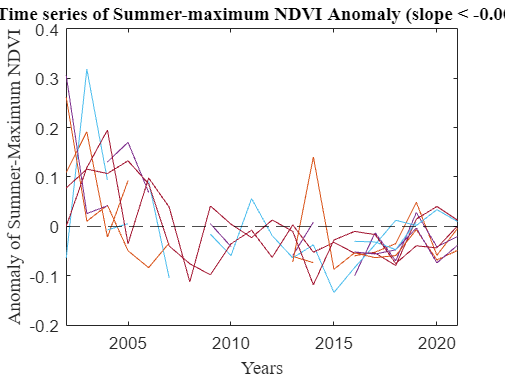

% plotting the time series of slope values less than -0.005
A_neg = T.trend_slopes < -0.005;
T_neg = [];
for i=1:27
    T_neg = [T_neg T{:,i}(A_neg)];
end
clear i; clear max_slope; clear min_slope; clear A;

T_neg = array2table(T_neg);
T_neg = renamevars(T_neg,T_neg.Properties.VariableNames, T.Properties.VariableNames);

for i = 1:sum(A_neg)
    plot(2002:2021, T_neg{i, 3:22} - T_neg{i, 23})
    xlim([2002,2021]);%ylim([0,0.65]);
    xlabel("Years", 'FontName', "Dialog"); 
    ylabel("Anomaly of Summer-Maximum NDVI", 'FontName', "Dialog");
    title("Time series of Summer-maximum NDVI Anomaly (slope < -0.005)", ...
        'FontName', "Dialog");
    hold on
end
clear A_neg; clear i; 
yline(0,'k--')
hold off
saveas(gcf,'Published_Plots\Figure_13.b.pdf')

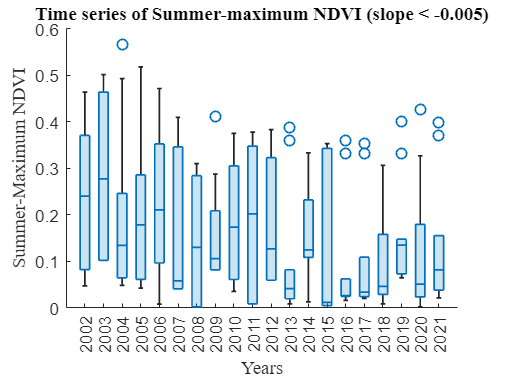

boxchart(T_neg{:,3:22})
set(gca,'XTickLabel',{'2002','2003','2004','2005', ...
    '2006','2007','2008','2009','2010','2011','2012','2013', ...
    '2014','2015','2016','2017', '2018','2019','2020','2021'});
xlabel("Years", 'FontName', "Dialog"); 
ylabel("Summer-Maximum NDVI", 'FontName', "Dialog");
title("Time series of Summer-maximum NDVI (slope < -0.005)", ...
    'FontName', "Dialog");

clear T_neg;